# Temperature and Heat Flux over X-43 Geometry

%% Constants and Variable Initialization
% Air foil and Wedge Geometry
x = 1.83; % [m]
alpha = 3.07; % [deg]
R_le = 0.003; % [m]
n_points = 40;

% atmospheric flow conditions
M = 7;
H = 29.0; % [km]
Vinf = 2107; % [m/s]
Tinf = 225.48; % [K]
Pinf = 1399.6; % [Pa]
T0 = 2435.13; % [K]
AoA = [4 6 8 10]; % [deg]
gamma = 1.362; % [-]
R = 287; % [J/(kg-K)]
Pr = 0.715; % Prandtl number
rec_fac = sqrt(Pr); % recovery factor
sigma = 5.67e-8; % stefan-botlzmann constant
epsilon = 0.95; % emissivity for carbon-carbon
CPw = 1700; % [J/(kg-K)], value for carbon-carbon
CPinf = 1006; % [J/(kg-K)], value for air
mu_ref = 1.827e-5; % [kg/(m-s)]
Tref = 291.15; % [K]
C = 120; % [K]

gp1 = gamma + 1;
gm1 = gamma - 1;
ggm1 = gamma / (gamma - 1);
s = zeros(length(AoA),1);


 %% Calculat heat flux
    for aoa = 1:length(AoA)
    
        for mach = 1:length(M)
        
        % Calculations: Leading Edge Stagnation Point Heat Flux
            % Freestream static conditions
            Tst(mach) = T0(mach) * (1 + gm1 / 2 * M(mach)^2)^(-1); % static temp
            P0(mach) = Pinf(mach) * (1 + gm1 / 2 * M(mach)^2)^(ggm1);
            rho_inf(mach) = Pinf(mach) / (R * Tinf(mach)); % air density at stagnation
            
            % normal shock relations to find heat flux at leading edge
            Pst(mach) = P0(mach) * ((gp1 * M(mach)^2) / (2 + gm1 * M(mach)^2))^(ggm1)*...
                (gp1 / (2 * gamma * M(mach)^2 - gm1))^(1 / gm1);
            rho_st(mach) = rho_inf(mach) * (gp1 * M(mach)^2) / (gm1 * M(mach)^2 + 2);
            mu_st(mach) = mu_ref * ((Tref + C) / (T0(mach) + C)) * (T0(mach) / Tref)^(3/2);
            
            % find enthalpy at wall under adiabatic conditions
            h_aw(mach) = CPinf * T0(mach) + 0.5 * Vinf(mach)^2;
            
            % rate of velocity at outer edge of boundary layer increases along
            % curvature from stagnation point
            Du_stDs(mach) = (1 / R_le) * sqrt(2 * (P0(mach) - Pinf(mach)) / rho_st(mach));
            
            % solve for Tiso 
            syms T_ISO 
            q_r_pt = sigma * epsilon * (T_ISO^4);
            h_staw_pt = CPinf * T0(mach) + 0.5 * Vinf(mach)^2;
            h_w_pt = CPw * T_ISO;
            q_st_gw_pt = 0.57 * Pr^(-0.6) * sqrt(rho_st(mach) * mu_st(mach)) * ...
                (h_staw_pt - h_w_pt) * sqrt(Du_stDs(mach));
            FUNC_pt = q_st_gw_pt - q_r_pt;
            func_pt = matlabFunction(FUNC_pt);
            Tiso_pt = fzero(func_pt,1000,optimset('Display','off'));
            
            % calculate enthalpies and heat flux
            h_w_pt_func = matlabFunction(h_w_pt);
            h_w_pt = h_w_pt_func(Tiso_pt);
            q_st_gw_pt_func = matlabFunction(q_st_gw_pt);
            q_st_gw_pt_val = q_st_gw_pt_func(Tiso_pt);
            
            Tiso(aoa,mach,1) = Tiso_pt;
            Qiso(aoa,mach,1) = q_st_gw_pt_val;
            
        
        % Leading Edge Tip Curvature and set limits on tip radius
            
            tip_min = 0;
            tip_max = (pi / 2) - deg2rad(alpha);
            dTip = (tip_max - tip_min) / 20;
            q_tip_gw(mach,1) = q_st_gw_pt_val;
            
            ilast = 20;
            for i = 2:ilast
                tip = tip_min + dTip * (i - 1);
                s(mach,i) = tip * R_le; % counterclockwise towards stage 3 surface
            
                G = (1 - 1 / (gamma * M(mach)^2)) * (tip^2 - 0.5 * tip * sin(4 * tip) + ...
                    ((1 - cos(4 * tip)) / 8)) + (4 / (gamma * M(mach)^2)) * ...
                    (tip^2 - tip * sin(2 * tip) + 0.5 * (1 - cos(2 * tip)));
        
                q_tip_gw(mach,i) = q_st_gw_pt_val * 2 * tip * sin(tip) * ((1 - 1 / (gamma * M(mach)^2)) * ...
                    cos(tip)^2 + 1 / (gamma * M(mach)^2)) * G^(-1/2);
        
                Qiso(aoa,mach,i) = q_tip_gw(mach,i);
                Tiso(aoa,mach,i) = Tiso_pt;
            
            end
        
        % Calculations: Leading-edge Flat Surface Heat Flux
            % lower surface
            if AoA(aoa) < 0 && abs(AoA(aoa)) > alpha % expansion fan
                theta = abs(AoA(aoa) + alpha);
                [M3(aoa,mach), P3(aoa,mach), T3(aoa,mach)] = PM_sol2(theta,M(mach),...
                    Pinf(mach),Tinf(mach),gamma);
            else % shock
                theta = AoA(aoa) + alpha;
                [M3(aoa,mach),P3(aoa,mach),T3(aoa,mach)] = ...
                    oblique2(theta,M(mach),Pinf(mach),Tinf(mach),gamma);
            end
            
            V3(aoa,mach) = M3(aoa,mach) * sqrt(R * gamma * T3(aoa,mach));
            rho3(aoa,mach) = P3(aoa,mach) / (R * T3(aoa,mach));
            h_eaw3(aoa,mach) = CPinf * T3(aoa,mach) + rec_fac * 0.5 * V3(aoa,mach)^2;
            
            % Stanton Number Calculations
            y = cosd(alpha) * R_le * sind(alpha);
            s_max = x / cosd(alpha);
            ds = (s_max - s(mach,ilast)) / (n_points - 1);
            
            % calculate the coordinates essentially over where the temperature and
            % stuff are computed
            syms T_ISO
            for i = 1:40
                ii = ilast + i;
                s(mach,ii) = s(mach,ilast) + i * ds;
                mu3 = mu_ref * ((Tref + C) / (T3(aoa,mach) + C)) * (T3(aoa,mach) / ...
                    Tref)^(3/2);
                Re_y = rho3(aoa,mach) * V3(aoa,mach) * (s(mach,ii) + y - s(mach,ilast)) / mu3;
            
                Tstar_T3 = 0.5 + 0.039 * M3(aoa,mach)^2 + 0.5 * (T_ISO / T3(aoa,mach));
                Cf_star = 0.664 * (Tstar_T3^(-1/6)) * (Re_y^(-1/2));
                Pr_star = (((T_ISO / T3(aoa,mach)) - 1) * (2 / (gm1 * M3(aoa,mach)^2)))^2;
                C_H = Cf_star / (2 * (Pr_star^(2/3)));
                
                h_w_flat = CPw * T_ISO;
                q_f_gw = C_H * rho3(aoa,mach) * V3(aoa,mach) * (h_eaw3(aoa,mach) - h_w_flat);
                q_r_flat = sigma * epsilon * T_ISO^4;
            
                func = q_f_gw - q_r_flat;
                FUNC = matlabFunction(func);
                Tiso(aoa,mach,ii) = fzero(FUNC,Tiso(aoa,mach),optimset('Display', 'off'));
                s_T(mach,i) = s(mach,ii);
                q_f_gw_func = matlabFunction(q_f_gw);
                Qiso(aoa,mach,ii) = q_f_gw_func(Tiso(aoa,mach,ii));
            
            end
        
        end
    
    end

## Plotting

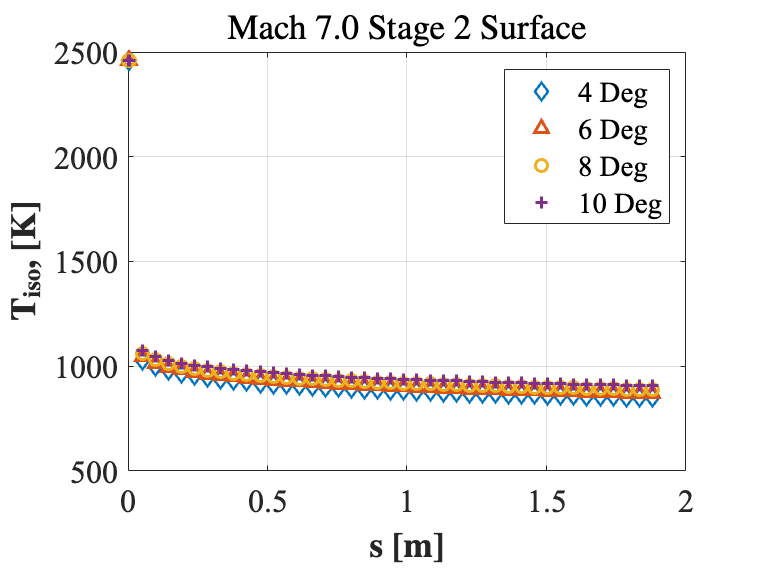

% Set Plotting parameters
set(0, 'DefaultAxesFontName', 'Times New Roman');  % font stlye
set(0, 'DefaultAxesFontSize', 16);       % font size
set(0, 'DefaultTextFontName', 'Times New Roman');  % font style
set(0, 'DefaultTextFontSize', 16);       % font size
set(0, 'DefaultLineLineWidth', 1.5);       % line width
set(0, 'DefaultLineMarkerSize', 6);      % marker size
set(0, 'DefaultTextInterpreter', 'latex');

fign = 1;
figure(fign)
plot(s(1,:),Tiso(1,:),'diamond',s(1,:),Tiso(2,:),'^',s(1,:),Tiso(3,:),'o',s(1,:),Tiso(4,:),'+');
xlabel('\textbf{s [m]}');
ylabel('\textbf{$\mathbf{T_{iso}}$, [K]}');
legend('4 Deg','6 Deg','8 Deg','10 Deg');
title('Mach 7.0 Stage 2 Surface')
grid on;

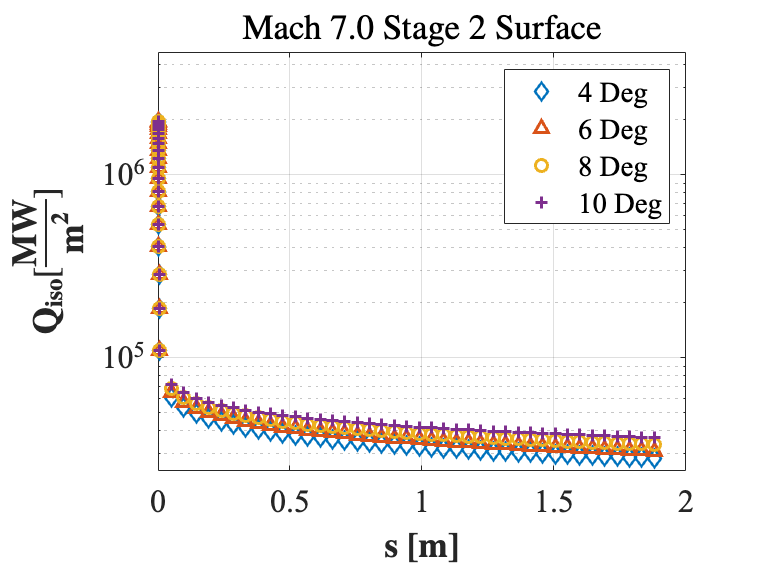

fign = fign + 1;

figure(fign)
semilogy(s(1,:),Qiso(1,:),'diamond',s(1,:),Qiso(2,:),'^',s(1,:),Qiso(3,:),'o',s(1,:),Qiso(4,:),'+');
xlabel('\textbf{s [m]}');
ylabel('$\mathbf{Q_{iso}}$[$\mathbf{\frac{MW}{m^2}}$]');
legend('4 Deg','6 Deg','8 Deg','10 Deg');
title('Mach 7.0 Stage 2 Surface')
ylim([24000 4700000])
grid on;

fign = fign + 1;















